  clear 


x_moto = [2,3,1,4,5,7,6]

x_moto =      2     3     1     4     5     7     6



K = fix(log2(length(x_moto)))+1

K = 3


L = 2.^[0:K-1]

L =      1     2     4



x= zeros(1,2^L(end));
x(1:length(x_moto))=x_moto;

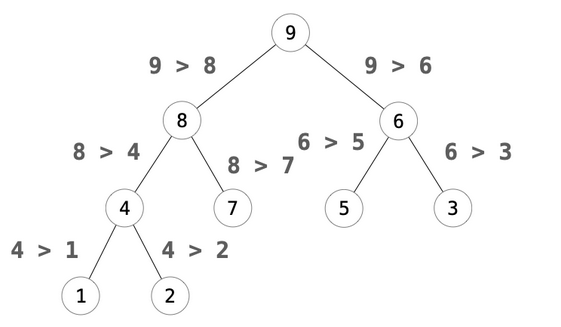

    if x(L(3)+0) < x(L(3)+1) % % 左が大きいにする。
        tmp = x(L(3)+0);
        x(L(3)+0) = x(L(3)+1);
        x(L(3)+1) = tmp;
    end
    x

x =      2     3     1     5     4     7     6     0     0     0     0     0     0     0     0     0



    if x(L(2)) < x(L(3)+0) 
        tmp = x(L(2));
        x(L(2)) = x(L(3)+0);
        x(L(3)+0) = tmp;
    end
    x

x =      2     5     1     3     4     7     6     0     0     0     0     0     0     0     0     0



    

    if x(L(3)+2) < x(L(3)+3) % % 左が大きいにする。
        tmp = x(L(3)+2);
        x(L(3)+2) = x(L(3)+3);
        x(L(3)+3) = tmp;
    end
    x

x =      2     5     1     3     4     7     6     0     0     0     0     0     0     0     0     0



    if x(L(2)+1) < x(L(3)+2) 
        tmp = x(L(2)+1);
        x(L(2)+1) = x(L(3)+2);
        x(L(3)+2) = tmp;
    end
    x

x =      2     5     7     3     4     1     6     0     0     0     0     0     0     0     0     0



    if x(L(2)) < x(L(2)+1) % % 左が大きいにする。
        tmp = x(L(2));
        x(L(2)) = x(L(2)+1);
        x(L(2)+1) = tmp;
    end
    x

x =      2     7     5     3     4     1     6     0     0     0     0     0     0     0     0     0



    if x(L(1)) < x(L(2)) 
        tmp = x(L(1));
        x(L(1)) = x(L(2));
        x(L(2)) = tmp;
    end
    x

x =      7     2     5     3     4     1     6     0     0     0     0     0     0     0     0     0


clear 
x_moto = [2,3,1,4,5,7,6]

x_moto =      2     3     1     4     5     7     6


K = fix(log2(length(x_moto)))+1

K = 3

L = 2.^[0:K-1]

L =      1     2     4


x= zeros(1,2^L(end));
x(1:length(x_moto))=x_moto;

for k=0:1   
 m=2*k;
 n=m+1;
    if x(L(3)+m) < x(L(3)+n) % % 左が大きいにする。
        tmp = x(L(3)+m);
        x(L(3)+m) = x(L(3)+n);
        x(L(3)+n) = tmp;
    end

    if x(L(2)+k) < x(L(3)+m) 
        tmp = x(L(2)+k);
        x(L(2)+k) = x(L(3)+m);
        x(L(3)+m) = tmp;
    end
end

    x

x =      2     5     7     3     4     1     6     0     0     0     0     0     0     0     0     0




    if x(L(2)) < x(L(2)+1) % % 左が大きいにする。
        tmp = x(L(2));
        x(L(2)) = x(L(2)+1);
        x(L(2)+1) = tmp;
    end
    x

x =      2     7     5     3     4     1     6     0     0     0     0     0     0     0     0     0



    if x(L(1)) < x(L(2)) 
        tmp = x(L(1));
        x(L(1)) = x(L(2));
        x(L(2)) = tmp;
    end
    x

x =      7     2     5     3     4     1     6     0     0     0     0     0     0     0     0     0


clear 
x_moto = [2,3,1,4,5,7,6]

x_moto =      2     3     1     4     5     7     6


K = fix(log2(length(x_moto)))+1

K = 3

L = 2.^[0:K-1]

L =      1     2     4


x= zeros(1,2^L(end));
x(1:length(x_moto))=x_moto;

NL=length(L);

for l=flip(2:NL) % 階層レベル 下の階層から処理する。
   K=L(l-1)-1;
   for k=0:K   
     m=2*k;
     n=m+1;
        if x(L(l)+m) < x(L(l)+n) % % 左が大きいにする。
            tmp = x(L(l)+m);
            x(L(l)+m) = x(L(l)+n);
            x(L(l)+n) = tmp;
        end
    
        if x(L(l-1)+k) < x(L(l)+m) 
            tmp = x(L(l-1)+k);
            x(L(l-1)+k) = x(L(l)+m);
            x(L(l)+m) = tmp;
        end
    end
end

% l=2 
% K=l-2;
%    for k=0:K 
%      m=2*k;
%      n=m+1;
%     if x(L(l)+m) < x(L(l)+n) % % 左が大きいにする。
%         tmp = x(L(l));
%         x(L(l)+m) = x(L(l)+n);
%         x(L(l)+n) = tmp;
%     end
%         if x(L(l-1)+k) < x(L(l)+m) 
%             tmp = x(L(l-1)+k);
%             x(L(l-1)+k) = x(L(l)+m);
%             x(L(l)+m) = tmp;
%         end
%    end
    x

x =      7     2     5     3     4     1     6     0     0     0     0     0     0     0     0     0
